# Projeto analogico 

- **Zeros**: São os valores de s (no domínio de Laplace) para os quais a função de transferência H(s) é **zero**. Ou seja, o filtro anula completamente o sinal nessas frequências (60Hz por exemplo).

- **Polos**: São os valores de s para os quais H(s) **tende ao infinito**. Eles indicam os pontos onde o sistema tem ganho máximo ou ressonância.

rad_s = 2 * pi;

[https://electroagenda.com/en/bainter-notch-filter-design-and-tuning/](https://electroagenda.com/en/bainter-notch-filter-design-and-tuning/)

- Gain = 4V/V

- Center Freq = 60Hz

- Bandwidth = 1Hz

- Ripple = 1dB

- Order = 2

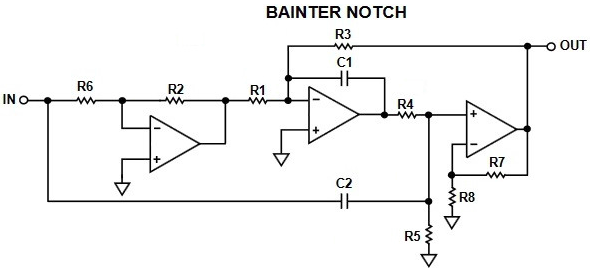

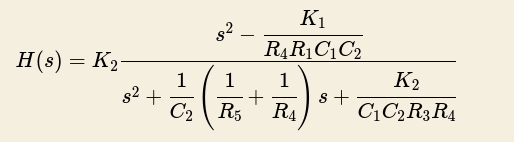

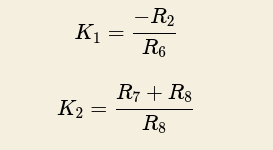

**Bessel Notch 60Hz**

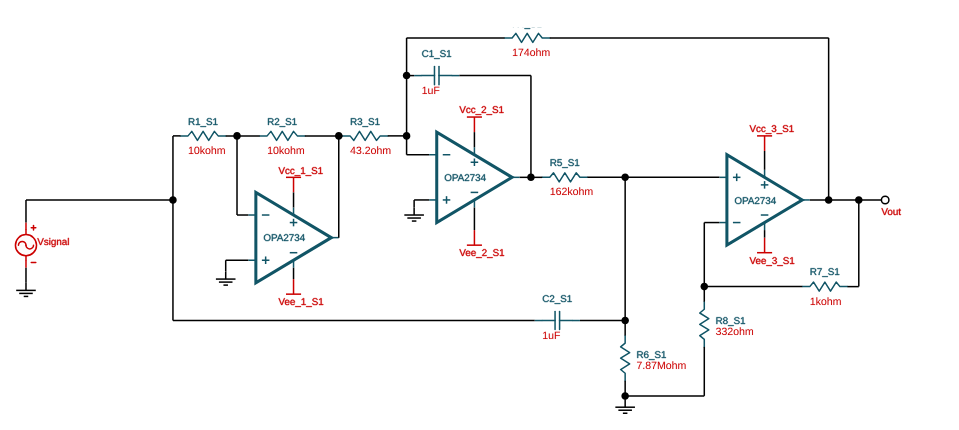

R1 = 43.2;
R2 = 10e3; %k ohm
R3 = 174;
R4 = 162e3; %k ohm
R5 = 7.87e6; %M ohm
R6 = 10e3; %k ohm
R7 = 1e3; %k ohm
R8 = 332;
C1 = 1e-6; %uF
C2 = 1e-6; %uF

K1 = -R2/R6

K1 = -1

K2 = (R7+R8)/R8

K2 = 4.0120


s = tf("s");
denominador = s^2 - (K1/(R4*R1*C1*C2))


denominador =
 
  s^2 + 1.429e05
 
Continuous-time transfer function.
Model Properties


divisor = s^2 + (1/C2)*((1/R5) + (1/R4))*s + K2/(C1*C2*R3*R4)


divisor =
 
  s^2 + 6.3 s + 1.423e05
 
Continuous-time transfer function.
Model Properties


H_ti = K2*(denominador/divisor)


H_ti =
 
   4.012 s^2 + 5.733e05
  ----------------------
  s^2 + 6.3 s + 1.423e05
 
Continuous-time transfer function.
Model Properties


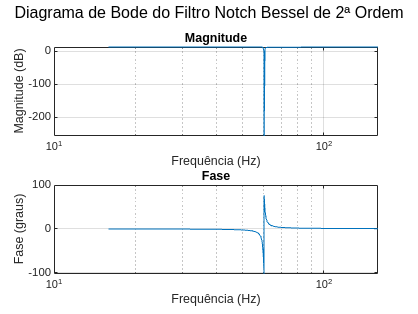


% Diagrama de Bode em Hz
[mag, phase, w] = bode(H_ti); % w está em rad/s
mag = squeeze(mag);
phase = squeeze(phase);
f = w / rad_s; % conversão para Hz

figure;
subplot(2,1,1);
semilogx(f, 20*log10(mag));
grid on;
title('Magnitude');
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
subplot(2,1,2);
semilogx(f, phase);
grid on;
title('Fase');
xlabel('Frequência (Hz)');
ylabel('Fase (graus)');
sgtitle('Diagrama de Bode do Filtro Notch Bessel de 2ª Ordem');

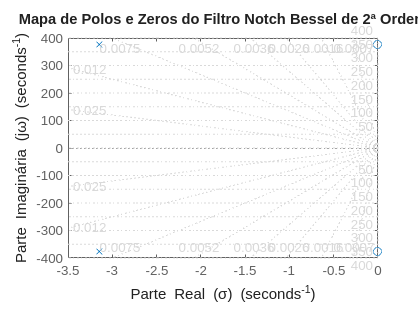


% Mapa de Polos e Zeros com labels ajustados
figure;
pzmap(H_ti);
grid on;
title('Mapa de Polos e Zeros do Filtro Notch Bessel de 2ª Ordem');
xlabel('Parte Real (σ)');
ylabel('Parte Imaginária (jω)');

**Butterworth Notch 60Hz**

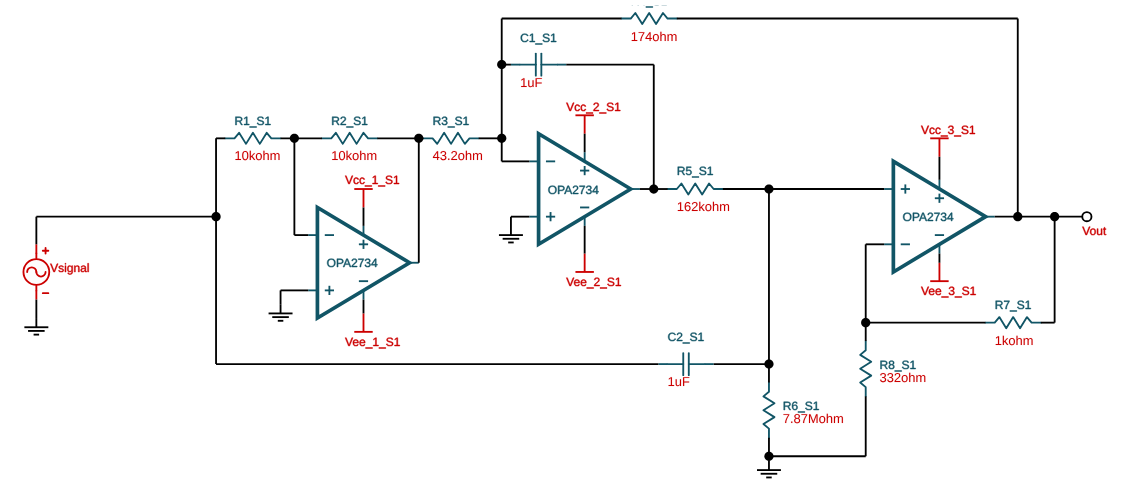

R1 = 43.2;
R2 = 10e3; %k ohm
R3 = 174;
R4 = 162e3; %k ohm
R5 = 7.87e6; %M ohm
R6 = 10e3; %k ohm
R7 = 1e3; %k ohm
R8 = 332;
C1 = 1e-6; %uF
C2 = 1e-6; %uF   

K1 = -R2/R6

K1 = -1

K2 = (R7+R8)/R8

K2 = 4.0120


s = tf("s");

denominador = s^2 - (K1/(R4*R1*C1*C2))


denominador =
 
  s^2 + 1.429e05
 
Continuous-time transfer function.
Model Properties


divisor = s^2 + (1/C2)*((1/R5) + (1/R4))*s + K2/(C1*C2*R3*R4)


divisor =
 
  s^2 + 6.3 s + 1.423e05
 
Continuous-time transfer function.
Model Properties



H_ti = K2*(denominador/divisor)


H_ti =
 
   4.012 s^2 + 5.733e05
  ----------------------
  s^2 + 6.3 s + 1.423e05
 
Continuous-time transfer function.
Model Properties


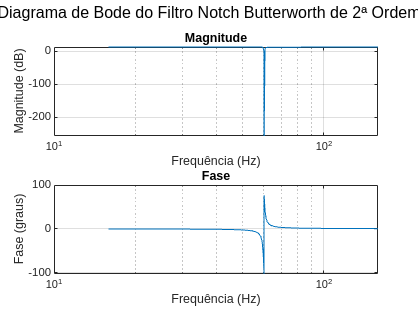


% Diagrama de Bode em Hz
[mag, phase, w] = bode(H_ti); % w está em rad/s
mag = squeeze(mag);
phase = squeeze(phase);
f = w / rad_s; % conversão para Hz

figure;
subplot(2,1,1);
semilogx(f, 20*log10(mag));
grid on;
title('Magnitude');
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
subplot(2,1,2);
semilogx(f, phase);
grid on;
title('Fase');
xlabel('Frequência (Hz)');
ylabel('Fase (graus)');
sgtitle('Diagrama de Bode do Filtro Notch Butterworth de 2ª Ordem');

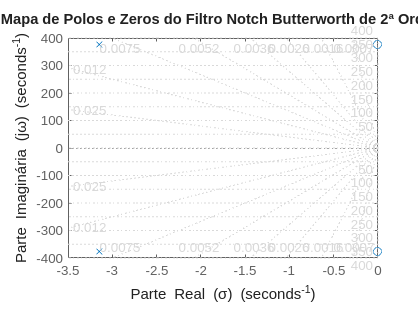


% Mapa de Polos e Zeros com labels ajustados
figure;
pzmap(H_ti);
grid on;
title('Mapa de Polos e Zeros do Filtro Notch Butterworth de 2ª Ordem');
xlabel('Parte Real (σ)');
ylabel('Parte Imaginária (jω)');